# main関数　速度最適化を行い，B-Spline曲線を表示する．

clear
% close all


## desired Points (X-Y)


% Q = [ 
%     0.0, 0.0;
%     1.0, 2.0;
%     3.0, 2.0;
%     3.0, 0.0;
%     5.0, 2.0;
%     6.0, 0.0;
%     ];
% 
% Q = [ 
%     0.0, 0.0;
%     0.0, 1.0;
%     0.0, 2.0;
%     0.0, 3.0;
%     0.0, 4.0;
%     0.0, 5.0;
%     5.0, 5.0;
%     5.0, 0.0;
%     0.0, 0.0;
%     ];

% Q = [
%     0.0, 0.0;
%     1.0, 1.0;
%     2.0, 2.0;
%     3.0, 3.0;
%     4.0, 4.0;
%     4.99, 4.99;
% %     5.0, 5.0;
%     5.01, 5.01;
%     6.0, 4.0;
%     7.0, 3.0;
%     8.0, 2.0;
%     9.0, 1.0;
%     10.0, 0.0;
%     9.0, -1.0;
%     8.0, -2.0;
%     7.0, -3.0;
%     6.0, -4.0;
%     5.0, -5.0;
%     4.0, -4.0;
%     3.0, -3.0;
%     2.0, -2.0;
%     1.0, -1.0;
%     0.0, 0.0;
%     ];

% Q = [
%     0.0, 0.0;
%     2.5, 2.5;
%     5.0, 5.0;
%     7.5, 2.5;
%     10.0, 0.0;
%     7.5, -2.5;
%     5.0, -5.0;
%     2.5, -2.5;
%     0.0, 0.0;
%     ];
    
%  
% Q = [ 
%     3.0, 0.0;
%     6.0, 3.0;
%     3.0, 6.0;
%     0.0, 3.0;
%     3.0, 0.0;
%     ];

% Q = [ 
%     0.0,   0.0;
%     10.0, 10.0;
%     10.0,  0.0;
%     0.0,  10.0;
%     0.0,   0.0;
%     ];

Q = [ 
    5.0, 0.0;
    10.0, 5.0;
    5.0, 10.0;
    0.0, 5.0;
    
%     5.0, 0.0;
%     10.0, 5.0;
%     5.0, 10.0;
%     0.0, 5.0;
%     
%     5.0, 0.0;
%     10.0, 5.0;
%     5.0, 10.0;
%     0.0, 5.0;
    
    5.0, 0.0;
    ];


n_CONTROL_POINT = length(Q);     % Number of Control Points
DEGREE = 3;              % Degree of B-Spline
n_KNOT = n_CONTROL_POINT + DEGREE + 1; % Number of Knots in Knot Vector
n_SAMPLING_CONTROL = 50;     % Number of Sampling / Control Points
n_SAMPLING = n_SAMPLING_CONTROL * (n_CONTROL_POINT-1)+1;  % Number of Sampling
SAMPLING_TIME = 1;        % Sampling time [s]
MAX_VELOCITY = 1.1;        % max Velocity [m/s]
MAX_ACCEL = 150;          % max Accelaration [mm/s^2]
MAX_POS_ERR = 0.01;    % max Position Error [mm]
MotorRatio = 1;     % Ratio of Motor

MASS = 5.33;
% Mass = 0;
VEL_C = 24.2020;
MAX_F = 100;


t = 0:n_SAMPLING-1;
t = t / t(end);

u = OpenUniformKnotVector(n_KNOT,DEGREE,n_CONTROL_POINT);
P = CalculateControlPoint(Q, u, DEGREE);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

## Calculate B-spline Curve

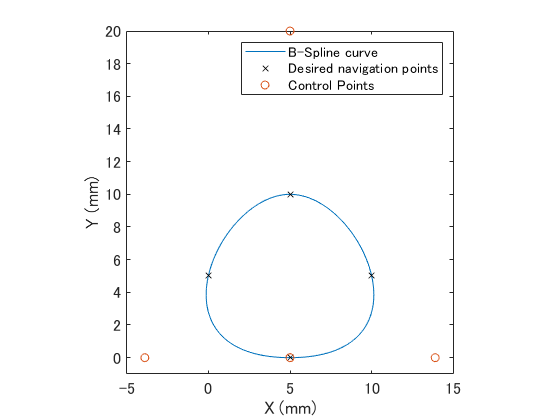

S = zeros(length(t),2);
for i = 1:length(t)
    for j =1:n_CONTROL_POINT
        b = BasisFunction(u,j,DEGREE,t(i));
        S(i,:) = S(i,:) + P(j,:)*b;
    end
end

S(1,:) = Q(1,:);
S_length = TotalLength(Q);

figure;
plot(S(:,1),S(:,2),Q(:,1),Q(:,2),'kx',P(:,1),P(:,2),'o');
set(gca, 'FontSize', 12);
xlabel('X (mm)');
ylabel('Y (mm)');
legend('B-Spline curve','Desired navigation points','Control Points');
axis equal;
axis([-5 15 -1 20]);

## 微分値を計算

DS = zeros(n_SAMPLING,2); % 1列目：X軸，2列目：Y軸
DS_norm = zeros(n_SAMPLING, 1);
DS_2 = zeros(n_SAMPLING,2); % 1列目：X軸，2列目：Y軸
DS_2_norm = zeros(n_SAMPLING, 1);

for i = 1: n_SAMPLING
    for j =1:n_CONTROL_POINT
        b = DifBasisFunction(1,u,j,DEGREE,t(i));  
        DS(i,:) = DS(i,:) + P(j,:)*b;
        DS_norm(i) = norm(DS(i,:));
        b = DifBasisFunction(2,u,j,DEGREE,t(i));  
        DS_2(i,:) = DS_2(i,:) + P(j,:)*b;
        DS_2_norm(i) = norm(DS_2(i,:));
    end
end

n_t = n_SAMPLING;

% S(length(t):length(t) + 150,:) = S(1:151,:);
% DS(length(t):length(t) + 150,:) = DS(1:151,:);
% DS_2(length(t):length(t) + 150,:) = DS_2(1:151,:);
% DS_norm(length(t):length(t) + 150,:) = DS_norm(1:151,:);
% 
% n_t = n_SAMPLING + 150;
% 
% t = 0:n_t-1;
% t = t / t(end);

figure;
subplot(2,1,1);
plot(t, DS(:,1),'b-',t, DS(:,2),'r--',t, DS_norm,'-.');
xlabel('u');
ylabel('V(mm/min)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

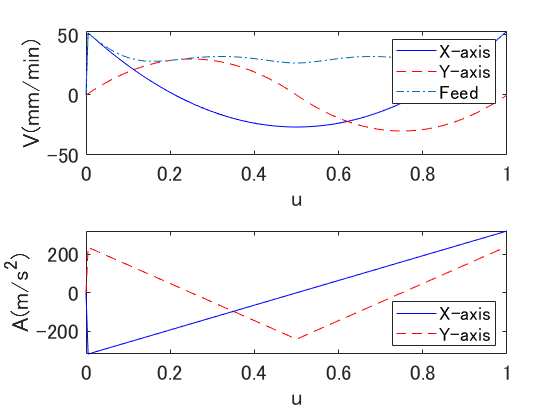

set(gca, 'FontSize', 16);


subplot(2,1,2); 
plot(t, DS_2(:,1),'b-',t, DS_2(:,2),'r--');
xlabel('u');
ylabel('A(m/s^2)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

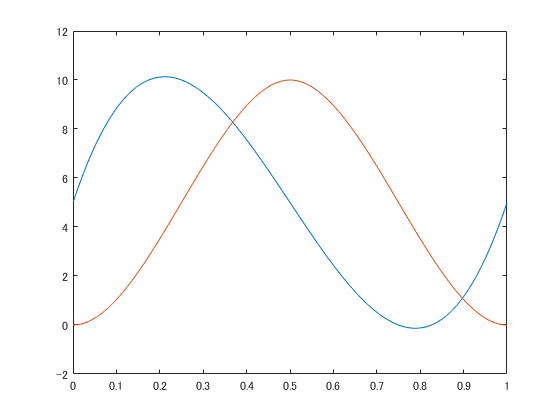

% ylim([-120 120]);

figure;
plot(t,S);

## 曲率

for i = 1: n_t
    for j =1:n_CONTROL_POINT
        MatDet = [DS(i, 1), DS(i, 2);
                  DS_2(i, 1), DS_2(i, 2)];
        R(i) = abs((DS(i,1)^2+DS(i,2)^2)^(3/2) / det(MatDet));
    end
end


## 速度最適化

DS_norm(1) = 1*10^(-10);
DS_norm(1) = 1*10^(-10);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocityXYaxis(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocityXZaxis(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,Fmax,Mass,VelC,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocity(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocityCXY(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,nt,ts,MotorRatio,SLength);
[V, fval, exitflag,output, cout,ceqout] = optimalEnergy(t,DS,DS_2,DS_norm,R,MAX_VELOCITY,MAX_ACCEL,MAX_POS_ERR,MAX_F,MASS,VEL_C,n_t,SAMPLING_TIME,MotorRatio,S_length);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     202    0.000000e+00    1.100e+00    1.631e+11
    1     404   -4.667486e+03    5.756e-01    2.778e+01    2.964e+00
    2     606   -3.951249e+03    3.102e-01    5.494e+03    5.947e+00
    3     808   -2.175591e+03    1.670e-03    8.048e+01    1.479e+00
    4    1010   -2.221069e+03    1.005e-05    2.792e+01    1.981e-02
    5    1212   -2.222810e+03    1.554e-06    3.912e+00    1.016e-01
    6    1415   -2.222813e+03    6.642e-07    3.919e+00    2.589e-01
    7    1618   -2.222815e+03    3.482e-07    3.923e+00    3.798e-01
    8    1821   -2.222816e+03    2.159e-07    3.925e+00    3.053e-01
    9    2024   -2.222816e+03    1.411e-07    3.926e+00    1.824e-01
   10    2227   -2.222816e+03    9.037e-08    3.767e+00    9.971e-02
   11    2430   -2.222817e+03    5.552e-08    2.752e+00    5.446e-02
   12    2633   -2.222817e+03    3.298e-08    2

% [V, fval, exitflag,output, cout,ceqout] = casadi_optimalVelocityXZaxis(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,Fmax,Mass,VelC,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = casadi_optimalEnergy(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,Mass,Fmax,VelC,nt,ts,MotorRatio,SLength);



## 速度計算

for i = 1: n_t-1
    V(i,2) = DS(i,1)*V(i)./DS_norm(i);
    V(i,3) = DS(i,2)*V(i)./DS_norm(i);
    V(i,4) = norm(V(i,2:3));
end


## 加速度計算

Accele = zeros(n_t, 3);
for i = 2: n_t-1
%     A(i, 1) = DS_2(i,1)*(V(i)/DS_norm(i))^2 + DS(i,1)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
%     A(i, 2) = DS_2(i,2)*(V(i)/DS_norm(i))^2 + DS(i,2)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
    
    Accele(i, 3) = (V(i+1)^2-V(i)^2) / 2*DS_norm(i)*(t(i+1)-t(i));
    Accele(i, 1) = -(DS_2(i,1)*(V(i)/DS_norm(i))^2 + DS(i,1)*Accele(i, 3)/DS_norm(i));
    Accele(i, 2) = DS_2(i,2)*(V(i)/DS_norm(i))^2 + DS(i,2)*Accele(i, 3)/DS_norm(i);
    
    Accele2(i, 1) = DS_2(i,1)*(V(i)/DS_norm(i))^2 + DS(i,1)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
    Accele2(i, 2) = DS_2(i,2)*(V(i)/DS_norm(i))^2 + DS(i,2)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
end

    Accele2(length(Accele2(:,1))+1, 1) = 0;


## Plot result

SRound = round(S,5).*(-1);
Feed = V.*60;
FeedRound = round(Feed,1);

figure;
subplot(2,1,1);
plot(t, Feed(:,2),'b-',t, Feed(:,3),'r--',t, Feed(:,1),'-.');
xlabel('u');
ylabel('V(mm/min)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

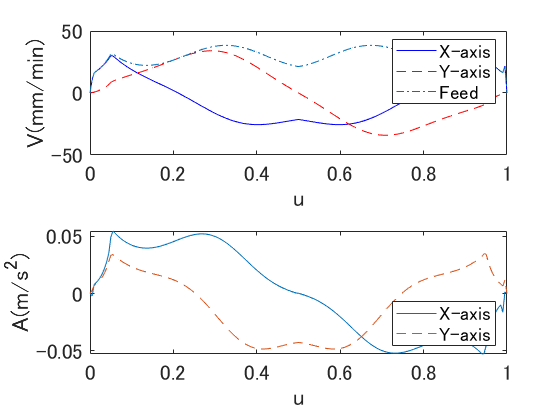

set(gca, 'FontSize', 16);


subplot(2,1,2); 
plot(t, Accele(:,1),t, Accele(:,2),'--');
xlabel('u');
ylabel('A(m/s^2)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

% ylim([-120 120]);

% subplot(2,1,2); 
% plot(t, Accele2);
% xlabel('t');
% ylabel('A(m/s)');
% legend('X-axis','Y-axis');

% figure
% plot(t,DS(:, 1), t, DS(:, 2));
% xlabel('t');
% ylabel('dC/du');
% legend('dX','dY','d2X','d2Y');
% 
% figure
% plot(t,DS_2(:, 1), t, DS_2(:, 2));
% xlabel('t');
% ylabel('d^2C/du^2');
% legend('X','Y');



## インプットデータを作成

## 一定速度を作成

dt = 0.01;
Const_timeEnd = 15;
t = 0:dt:Const_timeEnd;
START_INDEX = 74;
END_INDEX   = 275;
CONST_VELOCITY = 0.8;
WIDTH_INDEX = 20;

Const.Pos = zeros(length(t), 2);
Const.Vel = zeros(length(t), 3);
Const.NormVel = zeros(length(V(:,1)),3);

Const.NormVel(:, 3) = CONST_VELOCITY;

Const.Vel(1:START_INDEX, 3) = 0;
Const.Vel(100:250, 3) = CONST_VELOCITY;

for i = 1:WIDTH_INDEX
    Const.NormVel(i, 3) = CONST_VELOCITY * (1 - cos((i-1) * pi/(WIDTH_INDEX-1)))/2;
end

for i = 1:WIDTH_INDEX
    Const.NormVel(i+length(V(:,1))-WIDTH_INDEX, 3) = CONST_VELOCITY * (1 + cos((i-1) * pi/(WIDTH_INDEX-1)))/2;
end

j = 3;
JUDGE_AXIS = 2;

for i = 1:length(t)
    if j > length(Const.NormVel(:,1))-1
        Const.Pos(i,:) = S(1,:);
        Const.Vel(i,:) = 0;
        
    else
        orientation = (S(j+1,:) - S(j,:))./norm(S(j+1,:) - S(j,:));
        Const.NormVel(j,1:2) = orientation * Const.NormVel(j,3);

        if i == 1
            Const.Pos(1,:) = S(1,:);
            Const.Vel(1,1:2) = [0, 0];
        elseif Const.NormVel(j,JUDGE_AXIS) < 0
            Const.Pos(i,:) = Const.Pos(i-1,:) + Const.NormVel(j,1:2).*dt;
            Const.Vel(i,1:2) = Const.NormVel(j,1:2);
            
            if Const.Pos(i,JUDGE_AXIS) < S(j,JUDGE_AXIS)
                if j < length(Const.Vel(:,1))
                    j = j+1;
                end
                Const.Pos(i,:) = S(j,:);
            end

        elseif Const.NormVel(j,JUDGE_AXIS) > 0
            Const.Pos(i,:) = Const.Pos(i-1,:) + Const.NormVel(j,1:2).*dt;
            Const.Vel(i,1:2) = Const.NormVel(j,1:2);

            if Const.Pos(i,JUDGE_AXIS) > S(j,JUDGE_AXIS)
                if j < length(Const.Vel(:,1))
                    j = j+1;
                end
                Const.Pos(i,:) = S(j,:);
            end
        elseif Const.NormVel(j,JUDGE_AXIS) == 0
            if j < length(Const.Vel(:,1))
                j = j+1;
            end            
        end        
    end
end

for i = 1:length(Const.Vel(:,1))
    Const.Vel(i,3) = norm(Const.Vel(i, 1:2));
end

% figure;
% subplot(3,1,1);
% plot(t,Const.Vel(:,1),'b-',t,Const.Vel(:,2),'r--',t,Const.Vel(:,3));
% xlabel('t');
% ylabel('V(m/s)');
% legend('X-axis','Y-axis','Feed','norm(calculated)');
% set(gca, 'FontSize', 16);
% 
% subplot(3,1,2); 
% plot(t,Const.Pos(:,1),'b-',t,Const.Pos(:,2),'r--');
% xlabel('t');
% ylabel('Pos(m)');
% legend('X-axis','Y-axis','Location','southeast');
% set(gca, 'FontSize', 16);
% 
% subplot(3,1,3); 
% plot(Const.Pos(:,1),Const.Pos(:,2));
% % xlabel('t');
% % ylabel('Pos(m)');
% % legend('X-axis','Y-axis','Location','southeast');
% set(gca, 'FontSize', 16);


Const.Pos(:,1) = Const.Pos(:,1) - 5;

dt = 0.01;
timeEnd = 25;
t = 0:dt:timeEnd;

inputConstPosition = [t(:,1:283)', Const.Pos(924-75:1131,:)];
inputConstVelocity = [t(:,1:283)', Const.Vel(924-75:1131,1:2)];


for i = 1:START_INDEX
    inputConstVelocity(i, 2:3) = [0, 0];
end
for i = START_INDEX+1 : START_INDEX+2
    inputConstVelocity(i, 2:3) = inputConstVelocity(i+1, 2:3)./2;
end


for i = 1:START_INDEX+1
    inputConstPosition(i, 2:3) = [0, 0];
end
for i = END_INDEX : length(t)
    inputConstPosition(i, 2:3) = [0, 0];
end

for i = END_INDEX : length(t)
    inputConstVelocity(i, 2:3) = [0, 0];
end

inputConstPosition(:,1) = t';
inputConstVelocity(:,1) = t';

for i = 1:10
    inputConstVelocity(70 + i*220:i*220 + 290,2:3) = inputConstVelocity(70:290,2:3);
    inputConstPosition(70 + i*220:i*220 + 290,2:3) = inputConstPosition(70:290,2:3);
end

inputConstPositionMulti.time = [];
inputConstPositionMulti.signals.values = inputConstPosition(:,2:3);
inputConstPositionMulti.signals.dimensions = 2;

inputConstVelocityMulti.time = [];
inputConstVelocityMulti.signals.values = inputConstVelocity(:,2:3);
inputConstVelocityMulti.signals.dimensions = 2;

figure;
subplot(3,1,1);
plot(t,inputConstVelocity(:,2),'b-',t, inputConstVelocity(:,3),'r--');
xlabel('t');
ylabel('V(m/s)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

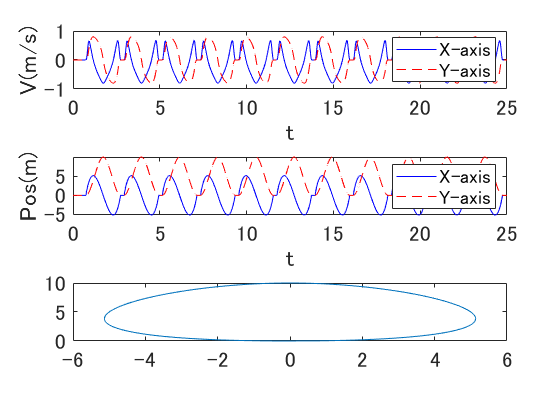

set(gca, 'FontSize', 16);

subplot(3,1,2); 
plot(t,inputConstPosition(:,2),'b-',t,inputConstPosition(:,3),'r--');
xlabel('t');
ylabel('Pos(m)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

subplot(3,1,3); 
plot(inputConstPosition(:,2),inputConstPosition(:,3));
% xlabel('t');
% ylabel('Pos(m)');
% legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

## 最適化

dt = 0.01;
t = 0:dt:timeEnd;
j = 2;

realPosition = zeros(length(t),2);
realVelocity = zeros(length(t),2);

judgeAxis = 2;

for i = 1:length(t)
    if j > length(V(:,1)-1)
        realPosition(i,:) = NaN;
        realVelocity(i,:) = NaN;
        
    else
        if i == 1
            realPosition(1,:) = S(1,:);
            realVelocity(1,:) = V(1,2:3);
        elseif V(j,3) < 0
            realPosition(i,:) = realPosition(i-1,:) + V(j,2:3).*dt;
            realVelocity(i,:) = V(j,2:3);
            if realPosition(i,judgeAxis) < S(j,judgeAxis)
                if j < length(V(:,1))
                    j = j+1;
                end
                realPosition(i,:) = S(j,:);
            end

        elseif V(j,3) > 0
            realPosition(i,:) = realPosition(i-1,:) + V(j,2:3).*dt;
            realVelocity(i,:) = V(j,2:3);
            if realPosition(i,judgeAxis) > S(j,judgeAxis)
                if j < length(V(:,1))
                    j = j+1;
                end
                realPosition(i,:) = S(j,:);
            end
        end
        

    end
end

realPosition(:,1) = realPosition(:,1) - 5;


for i = 1:74
    realVelocity(i, 1:2) = [0, 0];
end
for i = 75:76
    realVelocity(i, 1:2) = realVelocity(i+1, 1:2)./2;
end
% for i = 198:301
%     realVelocity(i, 1:2) = [0, 0];
% end
for i = 1:74
    realPosition(i, 1:2) = [0, 0];
end
for i = 275:length(t)
    realPosition(i, 1:2) = [0, 0];
end

inputOptiPosition = [t',realPosition];
inputOptiVelocity = [t',realVelocity];

for i = 1:10
    inputOptiVelocity(70 + i*220:i*220 + 290,2:3) = inputOptiVelocity(70:290,2:3);
    inputOptiPosition(70 + i*220:i*220 + 290,2:3) = inputOptiPosition(70:290,2:3);
end

inputOptiPositionMulti.time = [];
inputOptiPositionMulti.signals.values = inputOptiPosition(:,2:3);
inputOptiPositionMulti.signals.dimensions = 2;

inputOptiVelocityMulti.time = [];
inputOptiVelocityMulti.signals.values = inputOptiVelocity(:,2:3);
inputOptiVelocityMulti.signals.dimensions = 2;


save('input_Sircle_data','inputOptiPositionMulti','inputOptiVelocityMulti','t','inputConstPositionMulti','inputConstVelocityMulti');

figure;
subplot(3,1,1);
plot(t,realVelocity(:,1),'b-',t,realVelocity(:,2),'r--');
xlabel('t');
ylabel('V(m/s)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

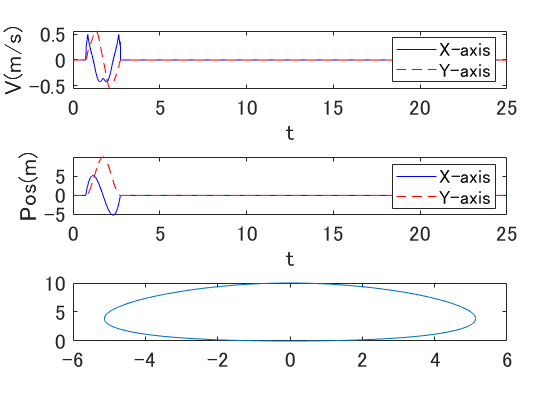

set(gca, 'FontSize', 16);

subplot(3,1,2); 
plot(t,realPosition(:,1),'b-',t,realPosition(:,2),'r--');
xlabel('t');
ylabel('Pos(m)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

subplot(3,1,3); 
plot(realPosition(:,1),realPosition(:,2));
% xlabel('t');
% ylabel('Pos(m)');
% legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);


figure;
subplot(3,1,1);
plot(t,inputOptiVelocity(:,2),'b-',t, inputOptiVelocity(:,3),'r--');
xlabel('t');
ylabel('V(m/s)');
legend('X-axis','Y-axis','norm(calculated)');

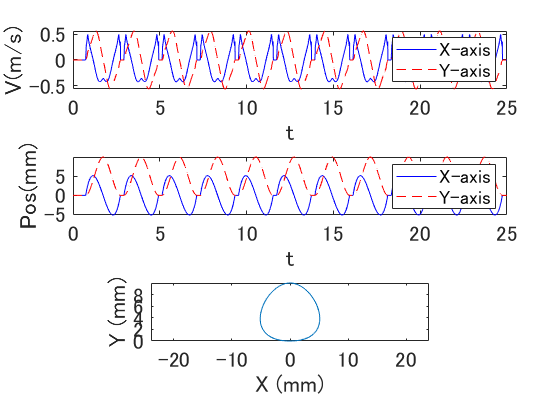

set(gca, 'FontSize', 16);

subplot(3,1,2); 
plot(t,inputOptiPosition(:,2),'b-',t,inputOptiPosition(:,3),'r--');
xlabel('t');
ylabel('Pos(mm)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

subplot(3,1,3); 
plot(inputOptiPosition(:,2),inputOptiPosition(:,3));
xlabel('X (mm)');
ylabel('Y (mm)');
% legend('X-axis','Y-axis','Location','southeast');
axis equal;
set(gca, 'FontSize', 16);

clearvars b i Amax exitflag j k MatDet MotorRatio nKnot nQ nSampling nt output PosErrMax SLength ts u Vmax

return
 

figure;
plot(S(:,1),S(:,2),Q(:,1),Q(:,2),'kx');
set(gca, 'FontSize', 14);
xlabel('X (mm)');
ylabel('Y (mm)');
legend('B-Spline curve','Desired navigation points');
axis equal;
axis([-5 15 -1 15]);

